[https://www.empirerc.com/hp-propconstants.htm](https://www.empirerc.com/hp-propconstants.htm)

*AE 14*10 - ***Aeronaut CAM Series Folders with 52, 47, 42mm centre hubs**

# Calculation maximum thrust / power / weight

PropellerConstant = 1.706; % - (propeller)
PowerFactor = 3.08; % - (propeller)
r = 0.3556/2; % m (propeller)
MaximumSpeed = 8640*2*pi*r/60; % m/s (motor)
eff_motor = 0.95; % - (motor)
eff_conv = 0.9; % - (converter)
rho = 1.225; % kg/m^3 (environnement)
g = 9.81; % m/s^2 (environnement)



A = pi*r*r;

Pd = PropellerConstant*(MaximumSpeed*60/(2*pi*r*1000))^PowerFactor % W

Pd = 1.3075e+03

Ps = Pd/eff_motor % W

Ps = 1.3763e+03

Pdc = Ps/eff_conv % W

Pdc = 1.5292e+03

Tsmax = (2*rho*A*Pd^2)^(1/3) % N

Tsmax = 74.6484



Thrust_to_weight = 0.4;
w = Tsmax/Thrust_to_weight

w = 186.6211

m = w/g

m = 19.0236


Thrust_to_weight = 0.2;
w = Tsmax/Thrust_to_weight

w = 373.2422

m = w/g

m = 38.0471

# Curves

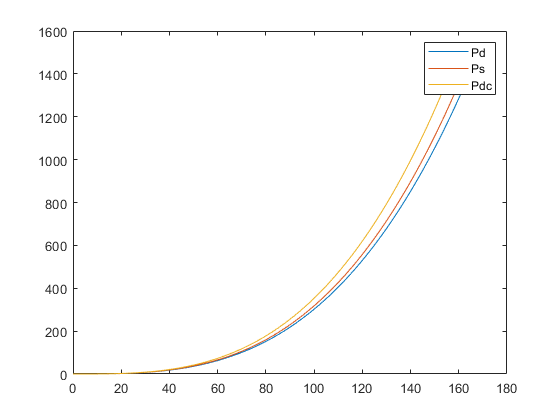

Thrust_to_weight = 0.4;
Speed = 0:0.1:MaximumSpeed;
Pd = PropellerConstant*(Speed*60/(2*pi*r*1000)).^PowerFactor; % W
Ps = Pd/eff_motor; % W
Pdc = Ps/eff_conv; % W
Tsmax = (2*rho*A*Pd.^2).^(1/3); % N
w = Tsmax/Thrust_to_weight;
m = w/g;

plot(Speed, Pd)
hold on
plot(Speed, Ps)
plot(Speed, Pdc)
legend('Pd','Ps','Pdc')

hold off

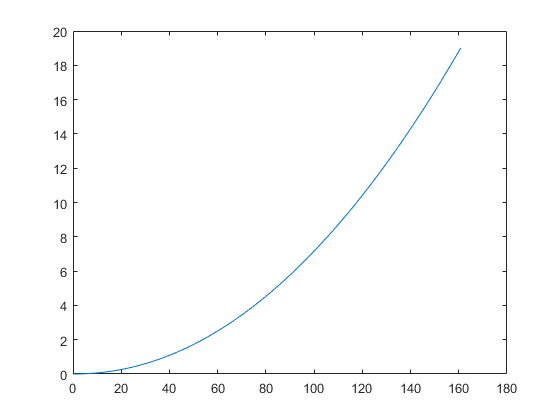

plot(Speed, m)